clear all;
close all;

# Assignment 2 Discrete Signal Proccessing 

On communication systems, a transmitter generates an information signal and sends it to a receiver through a wireless or wired channel. The physics wave where the information is modulated is a continuous signal (wave). Meanwhile, a computer cannot process such continuous waves because of the digital domain. Therefore, the receiver conducts an analog-to-digital conversion (ADC). Note that the transmitter makes the discrete signal at first and converts it into the continuous signal. That is, the digital-to-analog conversion (DAC) is performed.

In 2nd assignment, we learn a sampling method as the fundamental of the discrete signal processing.

Text recommendation: 

- Oppenheim, Alan V., and A. S. Willsky. *Signals and Systems*. Prentice Hall, 1982. ISBN: 9780138097318.

- Lecture video https://ocw.mit.edu/resources/res-6-007-signals-and-systems-spring-2011/video-lectures/

## Problem 1 Sampling theorem

Let the maximum frequency of signal $$x(t)$$ in time domain be $f_{max}$ [Hz], then the signal can be retrieved using the sampling frequency of more than (>) $2f_{max}$. This is termed as sampling theorem. So, **explain the proof of the sampling theorem.** In addition, why do we need the sampling frequency of more than (>) $2f_{max}$ not (>=) $2f_{max}$ or more? Here, let the spectrum of signal $$x(t)$$ be $X(\omega)$, then Fourier transform is given by,


$$X\left(\omega \;\right)=\frac{1}{\sqrt{2\pi \;}}\int_{-\infty \;}^{\infty \;} x\left(t\right)e^{-j\omega \;t} \mathrm{dt}$$


## Problem 2 Discrete Fourier Transform

(i) Continuous wave through the channel is sampled by ADC at the receiver. The receiver cannot read the continuous values, so the discrete process using sampling phase is important. Let sampling interval be $T_S$, then discrete signal $x_S \left(t\right)$ is given by,


$$x_S \left(t\right)=x\left(t\right)\sum_{k=-\infty \;}^{\infty \;} \delta \;\left(t-{\mathrm{kT}}_S \right)$$


Fourier transform of this signal is, 


$$X_S \left(\omega \;\right)=\frac{1}{\sqrt{2\pi \;}}\int_{-\infty \;}^{\infty \;} x_S \left(t\right)e^{-j\omega \;t} \mathrm{dt}=\frac{1}{\sqrt{2\pi \;}}\int_{-\infty \;}^{\infty \;} x\left(t\right)\sum_{k=-\infty \;}^{\infty \;} \delta \;\left(t-{\mathrm{kT}}_S \right)e^{-j\omega \;t} \mathrm{dt}=\sum_{k=-\infty \;}^{\infty \;} x\;\left({\mathrm{kT}}_S \right)e^{-j\omega {kT}_S }$$


**Derive this Fourier transform with your manual calculation.**

(ii) The above processing is termed as discrete time Fourier transform (DTFT). Next, mutliply the result of DTFT by $e^{j\omega \;T_S }$ and integrate them over a period of $f_S =\frac{1}{T_S }$. **Derive inverse DTFT with your manual calculation.**

(iii) For the result (i) and (ii), the range of summation is between [$-\infty \;$$\infty$]. So, unfortunately, we cannot calculate the DTFT in our computer. Therefore, on the computer, we prepare N samples of the signal. And, we assume that the sampled signal has periodicity. That is, the fomula is given by,


$$x_S \left({\mathrm{kT}}_S +{\mathrm{NT}}_S \right)=x_S \left({\mathrm{kT}}_S \right)$$


Then the DTFT is,


$$X_S \left(\omega \right)=\sum_{k=0}^{N-1} x\left({\mathrm{kT}}_S \right)e^{-j\omega \;{\mathrm{kT}}_S }$$


Here, $\omega$ is still the continuous variable. We would like to analyze on the computer finnally. $\omega$ must be discretized. We introduce integer $n$ and frequency resolution $\Delta \omega$. We obtain $\omega =n\Delta \;\omega$. Here, we remember the following relations,

- $X_S \left(\omega \right)$ is periodic function  with fundamental period of $\frac{1}{T_S }$

- One period of $X_S \left(\omega \right)$ is $N$ samples.

The frequency resolution is $\Delta \;\omega =2\pi \;/{\textrm{NT}}_S$. Then DTFT is,


$$X_S \left(n\Delta \;\omega \right)=\sum_{k=0}^{N-1} x\left({\mathrm{kT}}_S \right)e^{\frac{-\mathrm{j2}\pi \mathrm{nk}}{N}}$$


This formula is defined as discrete Frourier transform (DFT) of $x\left({\textrm{kT}}_S \right)$. OK, let's move on the problem. **Derive inverse DFT with your manual calculation.**

## Problem 3 Practice DFT

Let's practice how to use DFT with MATLAB simulation.

We calculate DFT of $x\left({nT}_S \right)=\cos \left(2\pi f_1 nT_S \right)$. Note that the fundamental frequency is assumed to $f_1 =1000$ Hz, sampling frequency is $f_{\textrm{samp}} =8000$ Hz. And the number of samples is $N=8$.

(i) First of all, calculate the DFT manually.

(ii) Using MATLAB simulation, calculate the DFT.

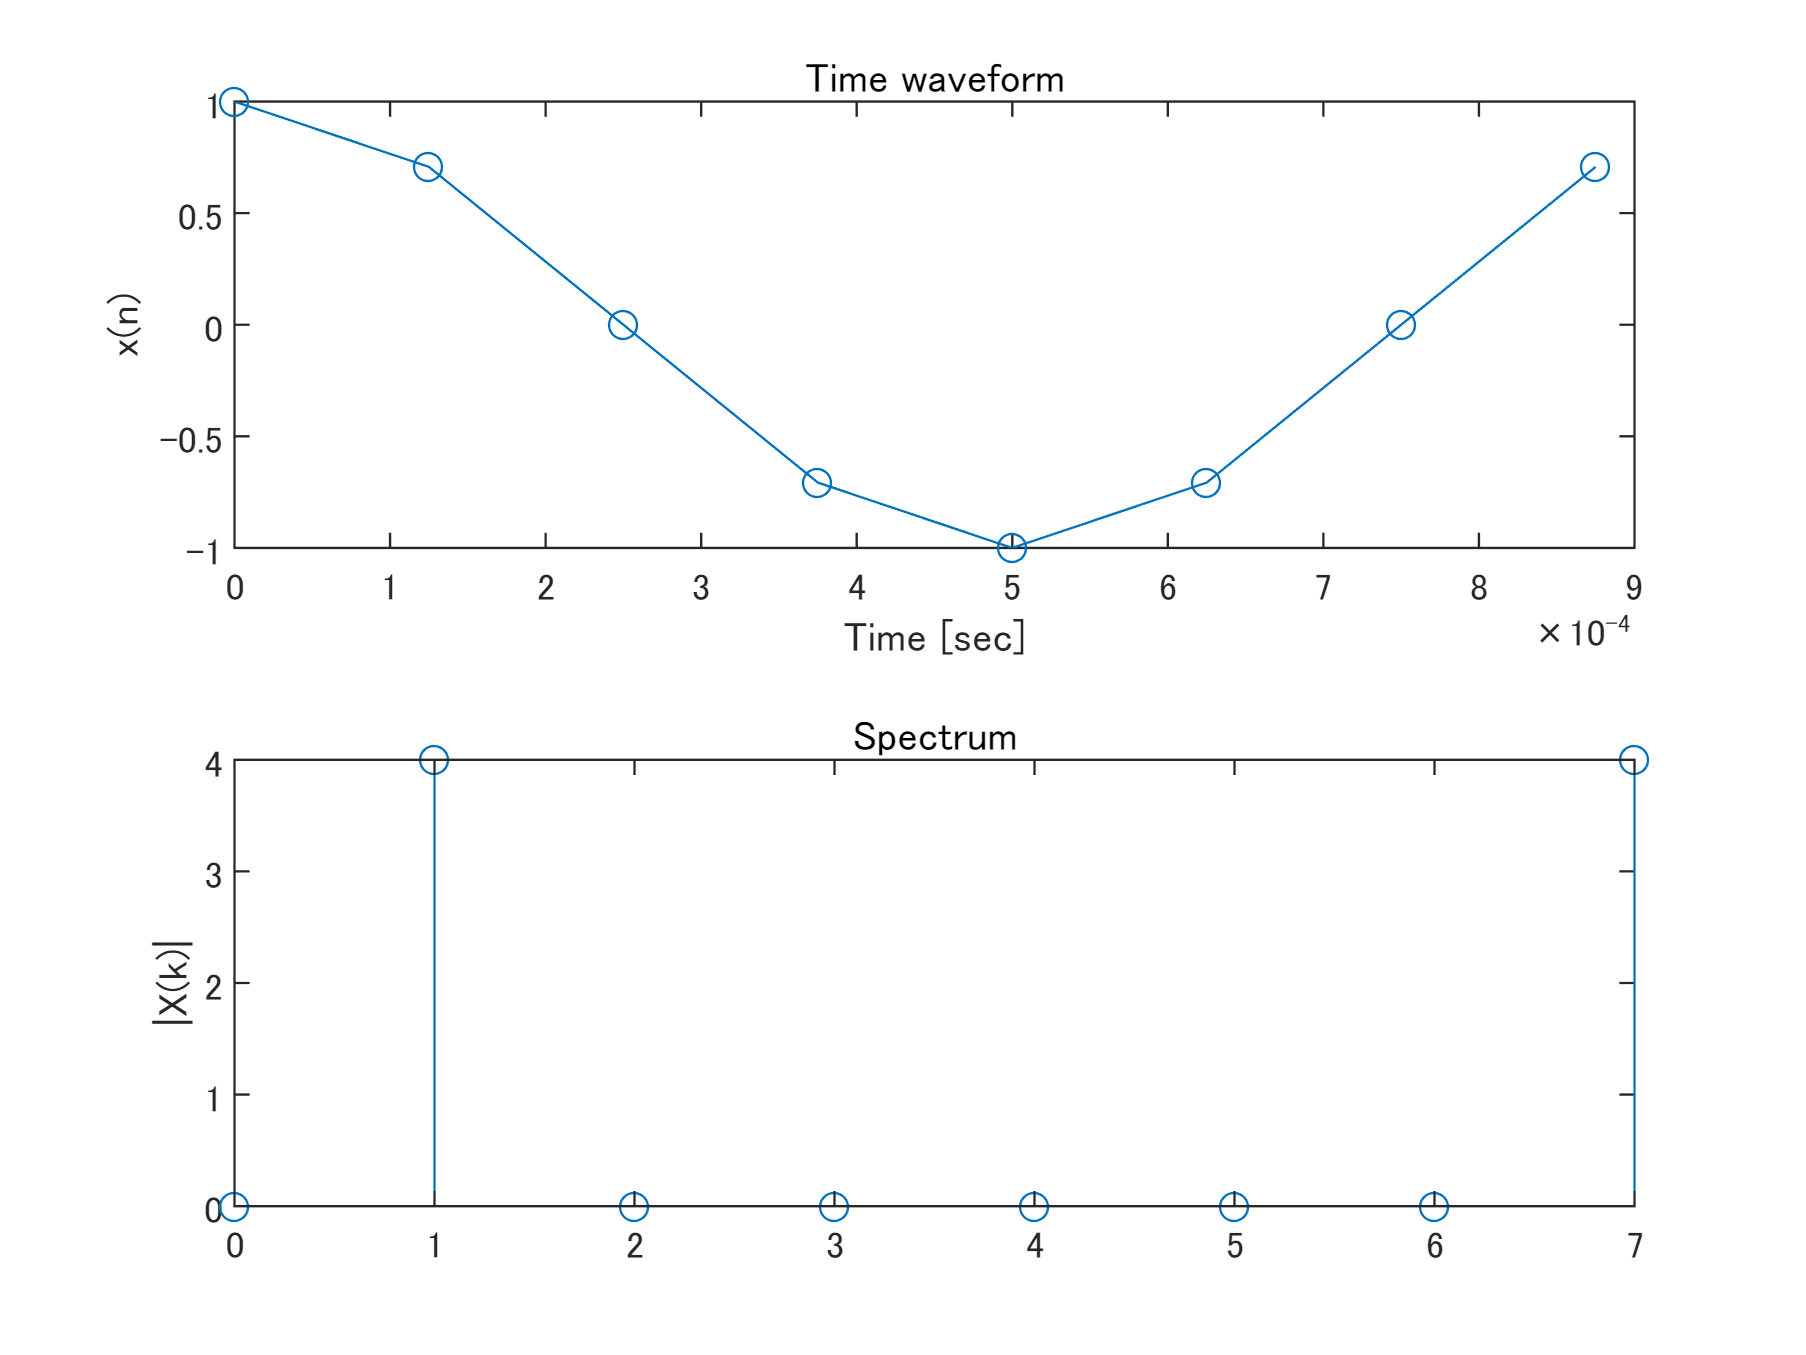

f1 = 1000;      % fudamental freq [Hz]
fs = 8000;      % sampling freq [Hz]
Ts = 1/fs;      % sampling time [sec]
N = 8;          % number of samples
n = 0:(N-1);    % array of sample numbers
x = cos(2*pi*f1*n*Ts);

tiledlayout(2,1);
nexttile;
plot(n*Ts,x,'-o');
xlabel("Time [sec]");
ylabel("x(n)");
title("Time waveform");
X = fft(x);
nexttile;
stem(n,abs(X));
ylabel("|X(k)|");
title("Spectrum");

See the spectrum, the peak values at x = 1 and 7 appear. x = 7 corresponds with seven times as fundamental frequency of 1,000Hz. Let's plot the graph.

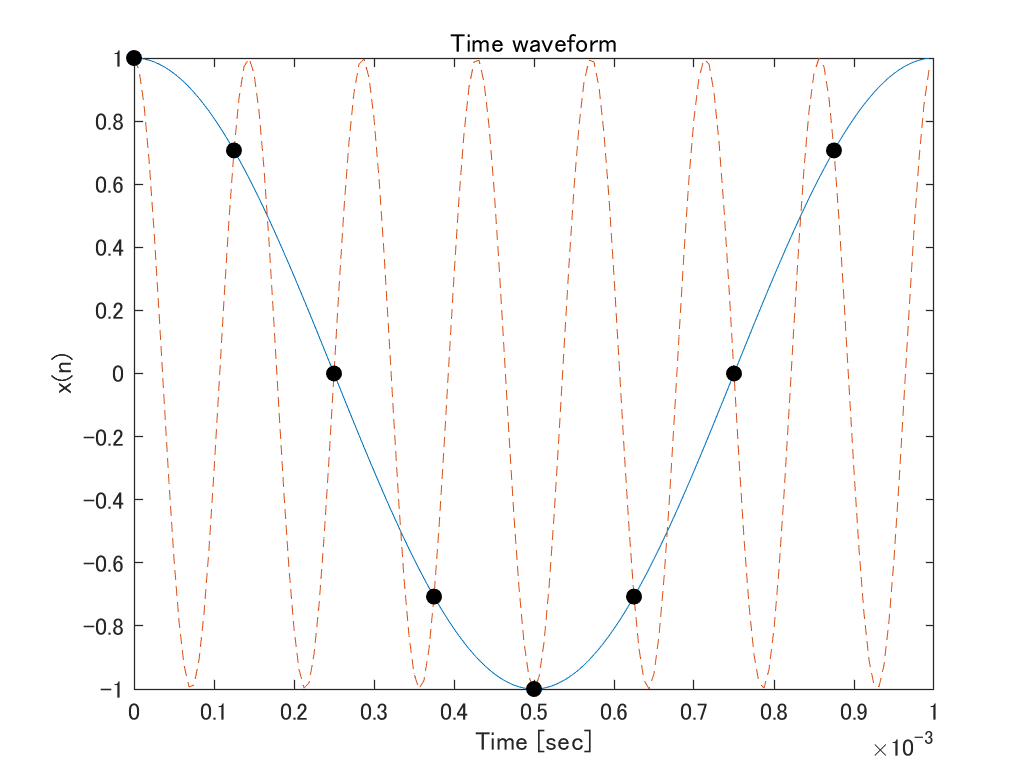

fs = 8000;      % Sampling frequency [Hz]
x1 = cos(2*pi*f1*(0:160-1)*(1/160000));
x7 = cos(2*pi*7*f1*(0:160-1)*(1/160000));
figure;
plot((0:160-1)*(1/160000),x1,'-');
hold on;
plot((0:160-1)*(1/160000),x7,'--');
scatter(n*Ts,x,'o','filled','k');
xlabel("Time [sec]");
ylabel("x(n)");
title("Time waveform");

Solid line shows the sin wave with fundamental frequency of 1,000 Hz. Dashed line shows the sin wave with fundamental frequency of 7,000 Hz. Black points show the samplng points when sampling with sampling frequency of 8,000 Hz. When the sin wave is reconstructed from the sampled points, there is possibility to reconstruct sin wave with fundamental frequency of either 1,000 Hz or 7,000 Hz. That is, we cannot distinguish which is the correct waveform. Therefore, when we see the discrete spectrum, the frequencies of 1,000Hz and 7,000Hz appear. **However**, from the sampling theorem, sampling frequency is two-fold of maximum frequency which original waveform has. Now, the sampling frequency is 8,000 Hz, so the maximum frequency which we can see is 4,000 Hz. Thus, frequency of 7,000 Hz does not appear. Well, what does the frequency of 7,000 Hz which we see in the above graph indicate? 

See the following figure. 

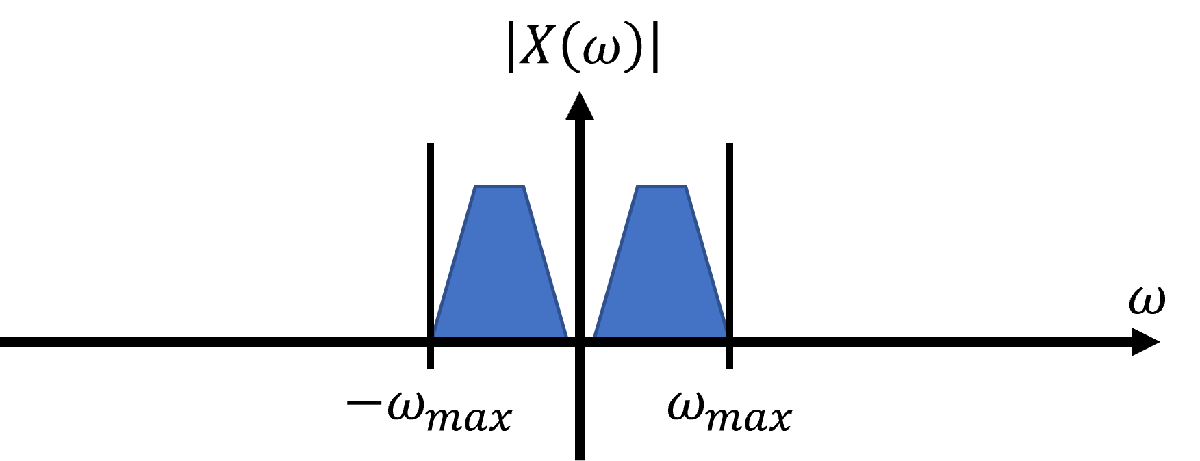

Let's sample the above signal with the frequency of two-fold of maximum frequency $\omega {\;}_{\max }$. Then, what happens to the spectrum when DFT is conducted?

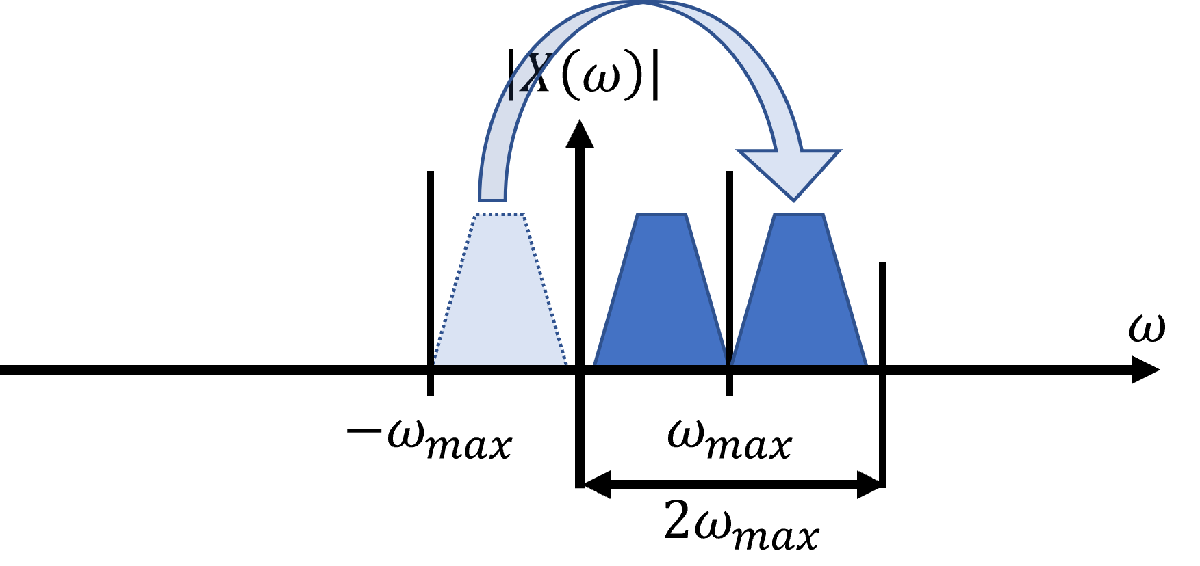

Such as the above figure, the component of minus frequency is copied next right to the plus frequency. The 7,000 Hz frequency component was actually the -1,000 Hz frequency component folded back. According to the explanation, let's arrange the x-axis of the spectrum.

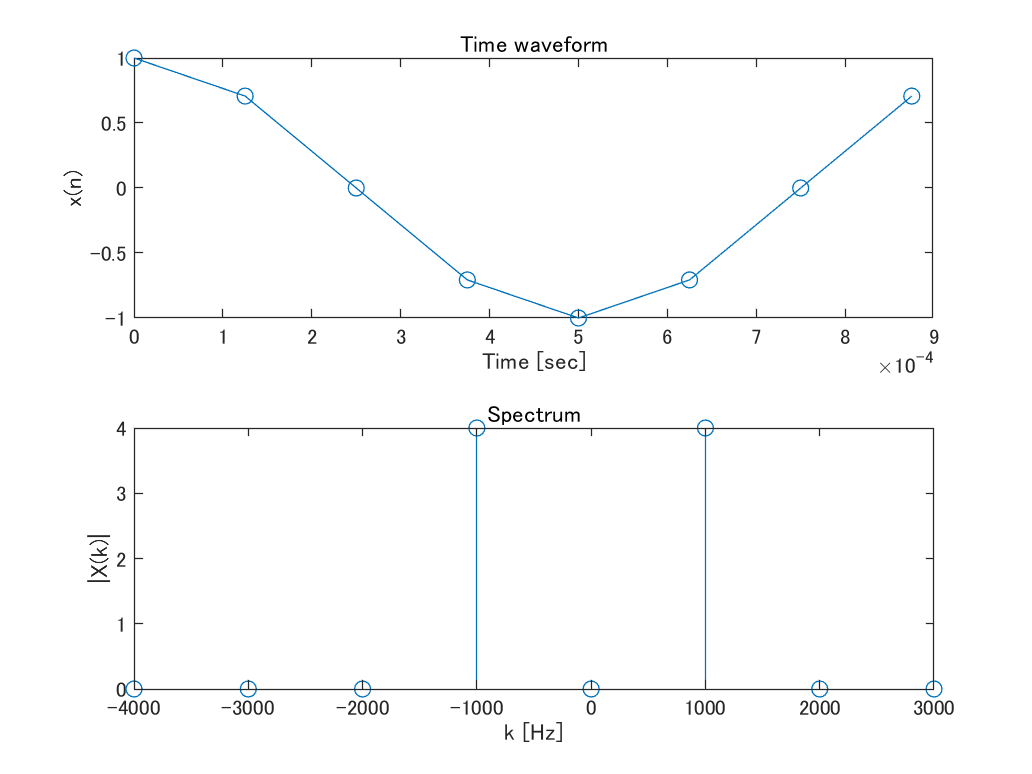

figure;
tiledlayout(2,1);
nexttile;
plot(n*Ts,x,'-o');
xlabel("Time [sec]");
ylabel("x(n)");
title("Time waveform");
X = fft(x);
k = fs*(-N/2:N/2-1)/N;
nexttile;
stem(k,abs(fftshift(X)));
xlabel("k [Hz]");
ylabel("|X(k)|");
title("Spectrum");

Here, move on the problems.

(2) Explain with equations, why the negative frequency is copied and appears as frequency components larger than the maximum frequency.

(3) Explain the relationship among sampling interval ( time resolution ) $T_S$, sampling frequency $f_S$, and frequency resolution $\Delta f$.

(4) Calulate the DFT of $x\left({nT}_S \right)=\cos \left(2\pi f_1 nT_S \right)+0\ldotp 7\cos \left(2\pi f_2 nT_S \right)$where $f_1 =1000$ Hz, $f_2 =500$ Hz,  $f_{\textrm{samp}} =8000$ Hz, $N=8$. Fix the following code that includes errors. The frequency of 500 Hz is not output.

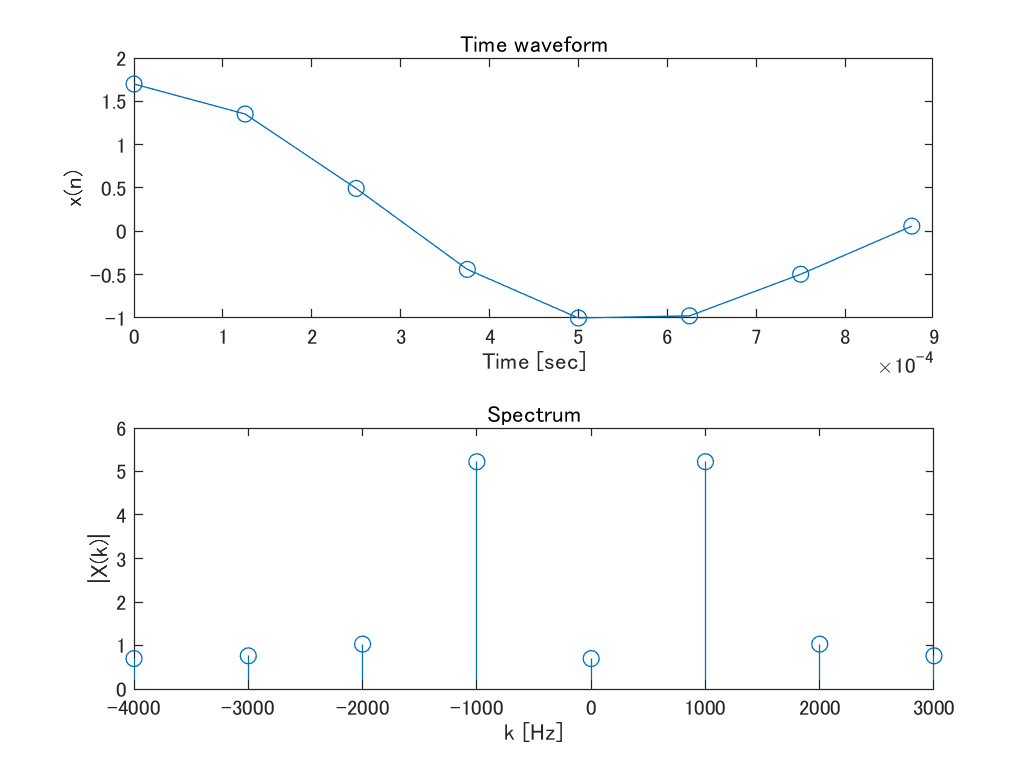

f1 = 1000;
f2 = 500;
fs = 8000;
Ts = 1/fs;
N = 16;
n = (0:N-1);   
x = cos(2*pi*f1*n*Ts)+0.7*cos(2*pi*f2*n*Ts);
figure;
tiledlayout(2,1);
nexttile;
plot(n*Ts,x,'-o');
xlabel("Time [sec]");
ylabel("x(n)");
title("Time waveform");
X = fft(x);
k = fs*(-N/2:N/2-1)/N;
nexttile;
stem(k,abs(fftshift(X)));
xlabel("k [Hz]");
ylabel("|X(k)|");
title("Spectrum");